clear; close all; clc

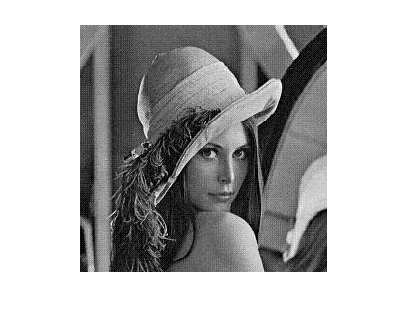

I = double(imread('lena.png')) / 255.0;
I = I(:,:,1);
imshow(I)

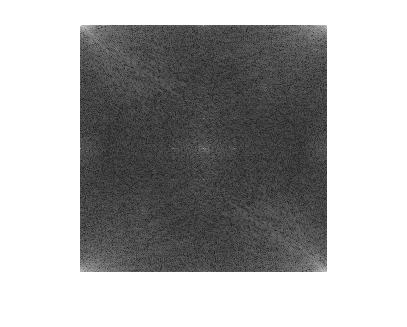

F = fft2(I);
FF = log(3+abs(F));
FF = FF / max(max(FF));
imshow(FF);

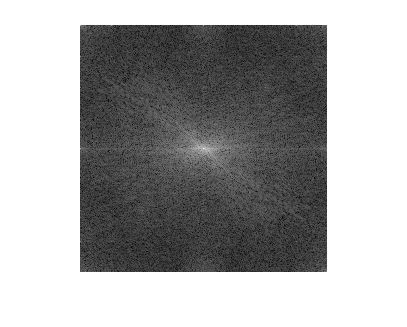

S = fftshift(F);
SS = log(1+abs(S));
SS = SS / max(max(SS));
imshow(SS);

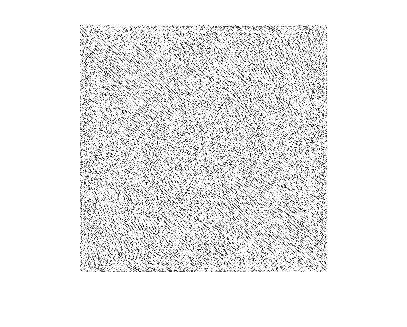

phase = angle(F);
imshow(abs(phase));

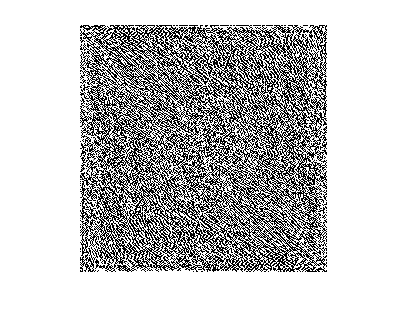

imshow(real(F));

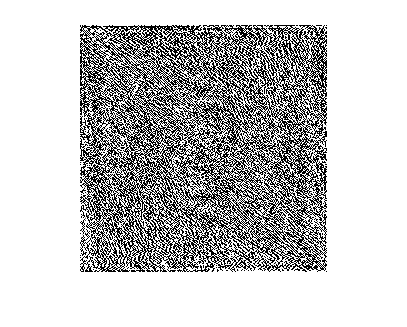

imshow(imag(F));

f = ifft2(F);
imshow(abs(f))

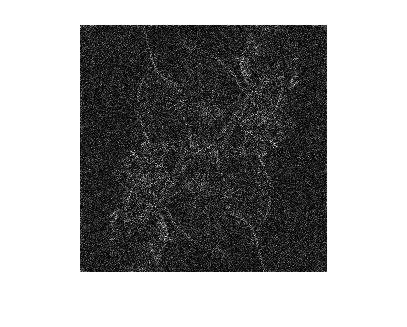

f = abs(ifft2(angle(F)));
f = f / max(max(f));
imshow(f);

% f = abs(ifft2(log(1+angle(F)))+1);
% m = max(max(f));
% f = f / m;
% for x = 1:size(f, 1)
%     for y = 1:size(f,2)
%         if f(x,y) < 0.626
%             f(x,y) = 0.0;
%         else
%             f(x,y) = 1.0;
%         end
%     end
% end
% imshow(f)
